# Equacions no lineals

## Iteració Simple

#### Practica 16

g=@(t)exp(-t);
gp=@(t)-exp(-t);
%fzero(f,[0,2])

[RES,alp,n]=itera(g,0,15,eps,eps)

RES = 1×15 struct array with fields:
    xn
    absGx
    absX


alp = 0.5673

n = 15

### Practica 17

fplot(gp)
hold on
fplot(@(x)1)

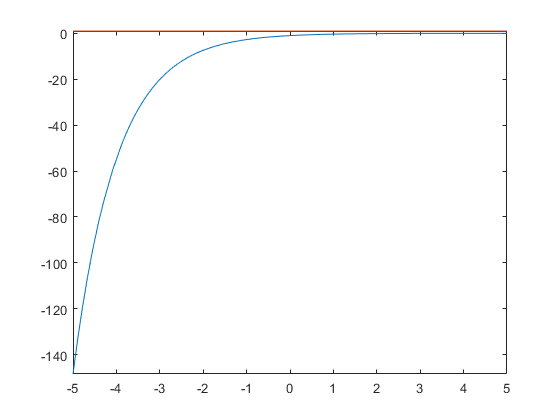

hold off

Com podem comprovar en el estudi a priori la derivada de la funció g en tot moment es menor que 1 ja que el seu limit a infinit és igual a 0, llavors podem afirmar que el mètode és convergent.

Si realitzem 1000 iteracions del mètode podem veure que el limit de l'error és a les 66 iteracions.

[RES,alp,n]=itera(g,0,70,eps,eps)

RES = 1×70 struct array with fields:
    xn
    absGx
    absX


alp = 0.5671

n = 70

## Aitken

### Problema 18

[RES,alp,n]=iteraAitk(g,0,15,eps,eps)

RES = 1×15 struct array with fields:
    xn
    absGx
    absX
    Aitk


alp = 0.5673

n = 15